# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** :박성찬        **

**학번 :201716180**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 :https://github.com/seongchan17/dsp-hw1-last-.git**

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 


n=-200:1:200

n =   -200  -199  -198  -197  -196  -195  -194  -193  -192  -191  -190  -189  -188  -187  -186  -185  -184  -183  -182  -181  -180  -179  -178  -177  -176  -175  -174  -173  -172  -171  -170  -169  -168  -167  -166  -165  -164  -163  -162  -161  -160  -159  -158  -157  -156  -155  -154  -153  -152  -151


x=5*(cos(0.49*pi*n)+cos(0.51*pi*n))

x =    10.0000   -0.0000   -9.9803    0.0000    9.9211    0.0000   -9.8229    0.0000    9.6858   -0.0000   -9.5106   -0.0000    9.2978   -0.0000   -9.0483    0.0000    8.7631   -0.0000   -8.4433    0.0000    8.0902    0.0000   -7.7051    0.0000    7.2897   -0.0000   -6.8455   -0.0000    6.3742   -0.0000   -5.8779    0.0000    5.3583   -0.0000   -4.8175    0.0000    4.2578    0.0000   -3.6812    0.0000    3.0902   -0.0000   -2.4869    0.0000    1.8738   -0.0000   -1.2533    0.0000    0.6279   -0.0000


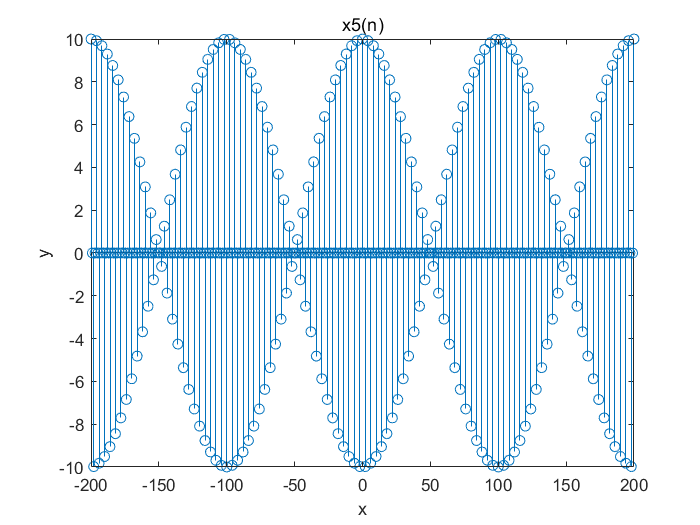

figure(1)
stem(n,x)
xlabel("x");ylabel("y");title("x5(n)");

2) 

n=0:1:100

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x=exp(-0.05*n).*sin(0.1*pi*n+pi/3)

x =     0.8660    0.9304    0.8999    0.7863    0.6084    0.3894    0.1540   -0.0737   -0.2726   -0.4267   -0.5253   -0.5643   -0.5458   -0.4769   -0.3690   -0.2362   -0.0934    0.0447    0.1654    0.2588    0.3186    0.3423    0.3310    0.2893    0.2238    0.1433    0.0567   -0.0271   -0.1003   -0.1570   -0.1932   -0.2076   -0.2008   -0.1754   -0.1358   -0.0869   -0.0344    0.0164    0.0608    0.0952    0.1172    0.1259    0.1218    0.1064    0.0823    0.0527    0.0208   -0.0100   -0.0369   -0.0577


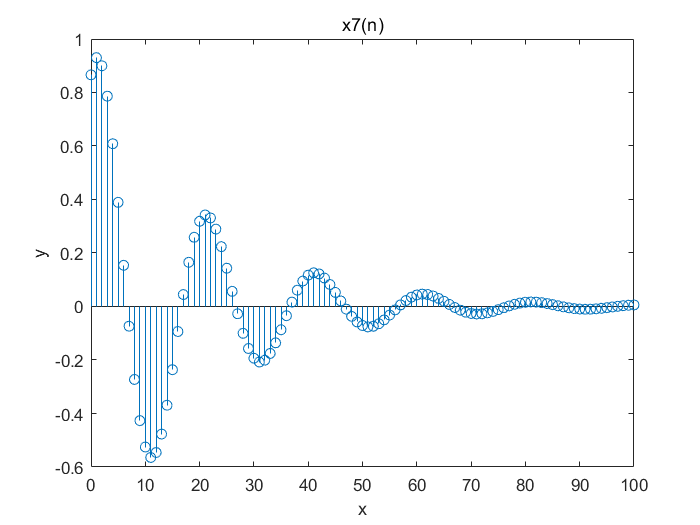

figure(2)
stem(n,x)
xlabel("x");ylabel("y");title("x7(n)");

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

n=0:1:100

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


b=[1,2,1]

b =      1     2     1


a=[1,-0.5,0.25]

a =     1.0000   -0.5000    0.2500


h=impz(b,a,n)

h =     1.0000
    2.5000
    2.0000
    0.3750
   -0.3125
   -0.2500
   -0.0469
    0.0391
    0.0312
    0.0059


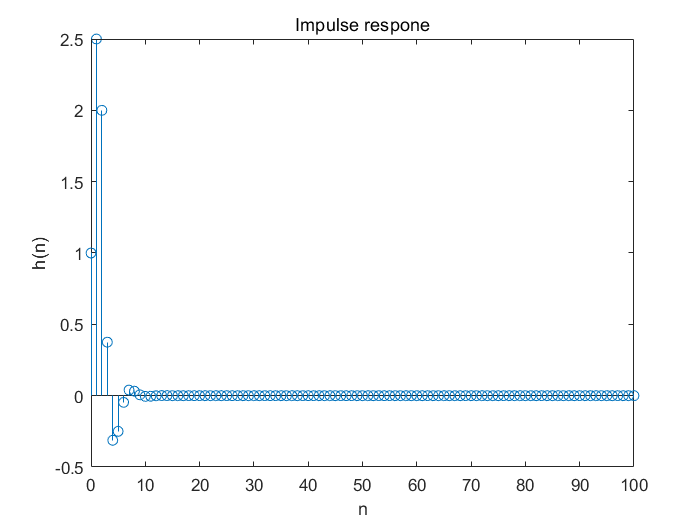

figure(3)
stem(n,h)
xlabel("n");ylabel("h(n)");title("Impulse respone");

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

ans=sum(abs(h))

ans = 6.5714

3) 만약 이 시스템의 입력이  x(n)=[5+3cos(0.2*pi*n)+4sin(0.6*pi*n]u(n) 이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

n=0:1:200

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


b=[1,2,1]

b =      1     2     1


a=[1,-0.5,0.25]

a =     1.0000   -0.5000    0.2500


x=(5+3*cos(0.2*pi*n)+4*sin(0.6*pi*n)).*ones(1,201)

x =     8.0000   11.2313    3.5759    1.7218    6.3772    2.0000   -1.2313    6.4241    8.2782    3.6228    8.0000   11.2313    3.5759    1.7218    6.3772    2.0000   -1.2313    6.4241    8.2782    3.6228    8.0000   11.2313    3.5759    1.7218    6.3772    2.0000   -1.2313    6.4241    8.2782    3.6228    8.0000   11.2313    3.5759    1.7218    6.3772    2.0000   -1.2313    6.4241    8.2782    3.6228    8.0000   11.2313    3.5759    1.7218    6.3772    2.0000   -1.2313    6.4241    8.2782    3.6228


y=filter(b,a,x) 

y =     8.0000   31.2313   47.6541   36.1241   19.5452   17.2177   12.8685    8.0913   20.7236   34.9423   35.8141   40.0256   45.0977   32.6474   18.4460   17.5373   13.3031    8.2287   20.6837   34.8880   35.7969   40.0306   45.1045   32.6495   18.4453   17.5364   13.3028    8.2288   20.6838   34.8880   35.7969   40.0305   45.1045   32.6495   18.4453   17.5364   13.3028    8.2288   20.6838   34.8880   35.7969   40.0305   45.1045   32.6495   18.4453   17.5364   13.3028    8.2288   20.6838   34.8880


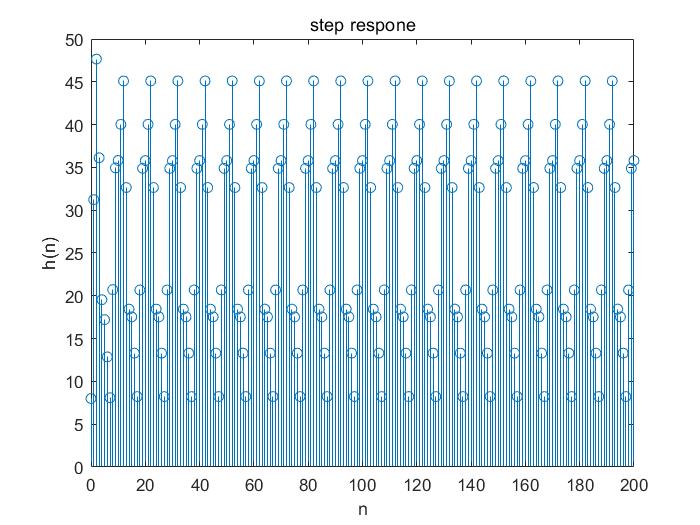

figure(4)
stem(n,y)
xlabel("n");ylabel("h(n)");title("step respone");

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

n=0:1:100

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


%y의 결과가 1*101 이라 n 범위를 정했습니다
k=[0:50]

k =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x=(0.8).^(k).*ones(1,51)

x =     1.0000    0.8000    0.6400    0.5120    0.4096    0.3277    0.2621    0.2097    0.1678    0.1342    0.1074    0.0859    0.0687    0.0550    0.0440    0.0352    0.0281    0.0225    0.0180    0.0144    0.0115    0.0092    0.0074    0.0059    0.0047    0.0038    0.0030    0.0024    0.0019    0.0015    0.0012    0.0010    0.0008    0.0006    0.0005    0.0004    0.0003    0.0003    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


h=(-0.9).^(k).*ones(1,51)

h =     1.0000   -0.9000    0.8100   -0.7290    0.6561   -0.5905    0.5314   -0.4783    0.4305   -0.3874    0.3487   -0.3138    0.2824   -0.2542    0.2288   -0.2059    0.1853   -0.1668    0.1501   -0.1351    0.1216   -0.1094    0.0985   -0.0886    0.0798   -0.0718    0.0646   -0.0581    0.0523   -0.0471    0.0424   -0.0382    0.0343   -0.0309    0.0278   -0.0250    0.0225   -0.0203    0.0182   -0.0164    0.0148   -0.0133    0.0120   -0.0108    0.0097   -0.0087    0.0079   -0.0071    0.0064   -0.0057


y=conv(x,h)

y =     1.0000   -0.1000    0.7300   -0.1450    0.5401   -0.1584    0.4047   -0.1545    0.3068   -0.1419    0.2351   -0.1257    0.1819   -0.1087    0.1418   -0.0924    0.1113   -0.0777    0.0879   -0.0647    0.0698   -0.0536    0.0556   -0.0441    0.0445   -0.0362    0.0356   -0.0296    0.0286   -0.0242    0.0230   -0.0197    0.0186   -0.0161    0.0150   -0.0131    0.0121   -0.0106    0.0098   -0.0086    0.0079   -0.0070    0.0064   -0.0057    0.0052   -0.0046    0.0042   -0.0037    0.0034   -0.0030


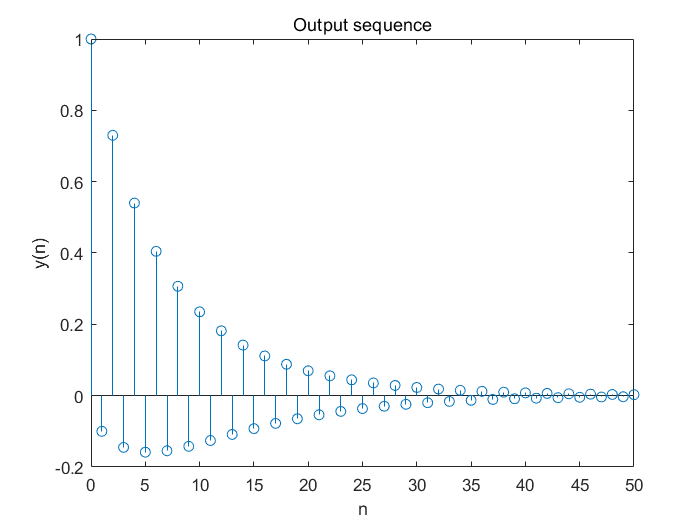

figure(5)
stem(n,y)
axis([0 50 -0.2 1])
%51개의 샘플 만을 보여주가 위해 범위를 조절 하였습니다
xlabel("n");ylabel("y(n)");title("Output sequence");

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. k

n=0:1:50

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


k=[0:25]

k =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25


x=(0.8).^(k).*ones(1,26)

x =     1.0000    0.8000    0.6400    0.5120    0.4096    0.3277    0.2621    0.2097    0.1678    0.1342    0.1074    0.0859    0.0687    0.0550    0.0440    0.0352    0.0281    0.0225    0.0180    0.0144    0.0115    0.0092    0.0074    0.0059    0.0047    0.0038


h=(-0.9).^(k).*ones(1,26)

h =     1.0000   -0.9000    0.8100   -0.7290    0.6561   -0.5905    0.5314   -0.4783    0.4305   -0.3874    0.3487   -0.3138    0.2824   -0.2542    0.2288   -0.2059    0.1853   -0.1668    0.1501   -0.1351    0.1216   -0.1094    0.0985   -0.0886    0.0798   -0.0718


y=conv(x,h)

y =     1.0000   -0.1000    0.7300   -0.1450    0.5401   -0.1584    0.4047   -0.1545    0.3068   -0.1419    0.2351   -0.1257    0.1819   -0.1087    0.1418   -0.0924    0.1113   -0.0777    0.0879   -0.0647    0.0698   -0.0536    0.0556   -0.0441    0.0445   -0.0362   -0.0320   -0.0229   -0.0208   -0.0144   -0.0135   -0.0090   -0.0088   -0.0056   -0.0058   -0.0035   -0.0038   -0.0021   -0.0025   -0.0013   -0.0017   -0.0007   -0.0012   -0.0004   -0.0008   -0.0002   -0.0005   -0.0001   -0.0004   -0.0000


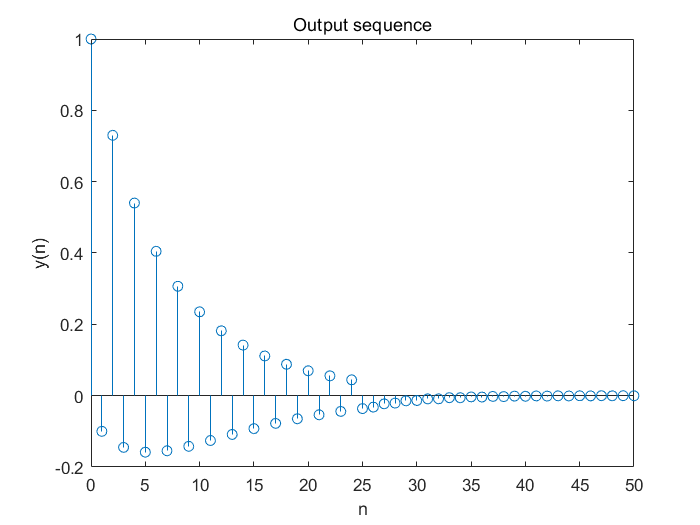

figure(6)
stem(n,y)
xlabel("n");ylabel("y(n)");title("Output sequence");

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 


n=0:1:50

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


k=[0:50]

k =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x=(0.8).^(k).*stepseq(0,0,50)

x =     1.0000    0.8000    0.6400    0.5120    0.4096    0.3277    0.2621    0.2097    0.1678    0.1342    0.1074    0.0859    0.0687    0.0550    0.0440    0.0352    0.0281    0.0225    0.0180    0.0144    0.0115    0.0092    0.0074    0.0059    0.0047    0.0038    0.0030    0.0024    0.0019    0.0015    0.0012    0.0010    0.0008    0.0006    0.0005    0.0004    0.0003    0.0003    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


a=(-0.9).^(k).*ones(1,51)

a =     1.0000   -0.9000    0.8100   -0.7290    0.6561   -0.5905    0.5314   -0.4783    0.4305   -0.3874    0.3487   -0.3138    0.2824   -0.2542    0.2288   -0.2059    0.1853   -0.1668    0.1501   -0.1351    0.1216   -0.1094    0.0985   -0.0886    0.0798   -0.0718    0.0646   -0.0581    0.0523   -0.0471    0.0424   -0.0382    0.0343   -0.0309    0.0278   -0.0250    0.0225   -0.0203    0.0182   -0.0164    0.0148   -0.0133    0.0120   -0.0108    0.0097   -0.0087    0.0079   -0.0071    0.0064   -0.0057


b=[1]

b = 1

y=filter(a,b,x)

y =     1.0000   -0.1000    0.7300   -0.1450    0.5401   -0.1584    0.4047   -0.1545    0.3068   -0.1419    0.2351   -0.1257    0.1819   -0.1087    0.1418   -0.0924    0.1113   -0.0777    0.0879   -0.0647    0.0698   -0.0536    0.0556   -0.0441    0.0445   -0.0362    0.0356   -0.0296    0.0286   -0.0242    0.0230   -0.0197    0.0186   -0.0161    0.0150   -0.0131    0.0121   -0.0106    0.0098   -0.0086    0.0079   -0.0070    0.0064   -0.0057    0.0052   -0.0046    0.0042   -0.0037    0.0034   -0.0030


figure(7)
stem(n,y)
xlabel("n");ylabel("y(n)");title("Output sequence");

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

h=(0.9).^(abs(n))

h =     1.0000    0.9000    0.8100    0.7290    0.6561    0.5905    0.5314    0.4783    0.4305    0.3874    0.3487    0.3138    0.2824    0.2542    0.2288    0.2059    0.1853    0.1668    0.1501    0.1351    0.1216    0.1094    0.0985    0.0886    0.0798    0.0718    0.0646    0.0581    0.0523    0.0471    0.0424    0.0382    0.0343    0.0309    0.0278    0.0250    0.0225    0.0203    0.0182    0.0164    0.0148    0.0133    0.0120    0.0108    0.0097    0.0087    0.0079    0.0071    0.0064    0.0057


k=-100:100

k =   -100   -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51


w=(pi/100)*k

w =    -3.1416   -3.1102   -3.0788   -3.0473   -3.0159   -2.9845   -2.9531   -2.9217   -2.8903   -2.8588   -2.8274   -2.7960   -2.7646   -2.7332   -2.7018   -2.6704   -2.6389   -2.6075   -2.5761   -2.5447   -2.5133   -2.4819   -2.4504   -2.4190   -2.3876   -2.3562   -2.3248   -2.2934   -2.2619   -2.2305   -2.1991   -2.1677   -2.1363   -2.1049   -2.0735   -2.0420   -2.0106   -1.9792   -1.9478   -1.9164   -1.8850   -1.8535   -1.8221   -1.7907   -1.7593   -1.7279   -1.6965   -1.6650   -1.6336   -1.6022


H=h*(exp(-j*pi/100)).^(n'*k)

H =    0.5288 + 0.0000i   0.5263 + 0.0054i   0.5239 + 0.0158i   0.5265 + 0.0260i   0.5289 + 0.0312i   0.5263 + 0.0368i   0.5241 + 0.0474i   0.5269 + 0.0575i   0.5292 + 0.0627i   0.5265 + 0.0685i   0.5245 + 0.0794i   0.5276 + 0.0895i   0.5297 + 0.0946i   0.5269 + 0.1008i   0.5252 + 0.1120i   0.5284 + 0.1221i   0.5305 + 0.1273i   0.5276 + 0.1339i   0.5261 + 0.1456i   0.5296 + 0.1558i   0.5315 + 0.1611i   0.5285 + 0.1682i   0.5273 + 0.1804i   0.5310 + 0.1908i   0.5328 + 0.1963i   0.5298 + 0.2040i   0.5288 + 0.2168i   0.5328 + 0.2274i   0.5345 + 0.2333i   0.5314 + 0.2417i   0.5307 + 0.2552i   0.5350 + 0.2662i   0.5366 + 0.2725i   0.5334 + 0.2818i   0.5331 + 0.2961i   0.5377 + 0.3076i   0.5393 + 0.3144i   0.5359 + 0.3248i   0.5360 + 0.3402i   0.5411 + 0.3523i   0.5425 + 0.3599i   0.5392 + 0.3714i   0.5397 + 0.3881i   0.5452 + 0.4011i   0.5466 + 0.4096i   0.5432 + 0.4227i   0.5443 + 0.4409i   0.5503 + 0.4550i   0.5517 + 0.4647i   0.5484 + 0.4796i


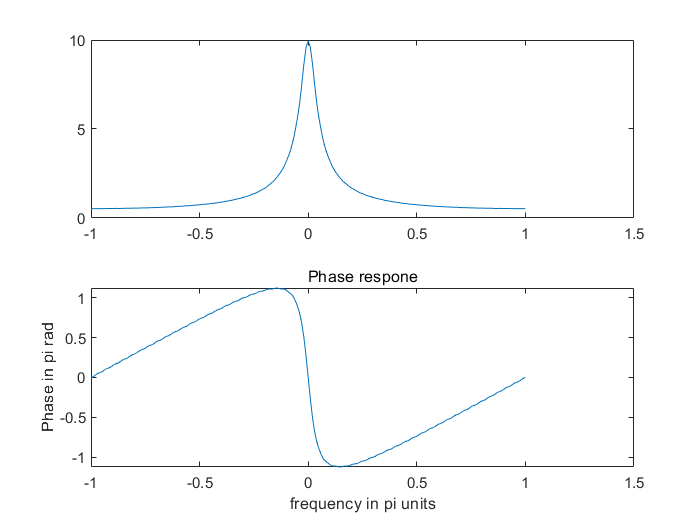

H2 =    0.5263 - 0.0000i   0.5263 + 0.0078i   0.5263 + 0.0157i   0.5264 + 0.0235i   0.5264 + 0.0314i   0.5265 + 0.0392i   0.5266 + 0.0471i   0.5266 + 0.0550i   0.5267 + 0.0630i   0.5268 + 0.0710i   0.5270 + 0.0790i   0.5271 + 0.0870i   0.5273 + 0.0951i   0.5274 + 0.1032i   0.5276 + 0.1114i   0.5278 + 0.1197i   0.5280 + 0.1280i   0.5283 + 0.1364i   0.5285 + 0.1448i   0.5288 + 0.1534i   0.5291 + 0.1620i   0.5294 + 0.1707i   0.5297 + 0.1794i   0.5301 + 0.1883i   0.5304 + 0.1973i   0.5308 + 0.2064i   0.5312 + 0.2157i   0.5317 + 0.2250i   0.5321 + 0.2345i   0.5326 + 0.2441i   0.5331 + 0.2539i   0.5337 + 0.2638i   0.5342 + 0.2739i   0.5348 + 0.2841i   0.5355 + 0.2946i   0.5362 + 0.3052i   0.5369 + 0.3161i   0.5376 + 0.3271i   0.5384 + 0.3384i   0.5393 + 0.3500i   0.5401 + 0.3617i   0.5411 + 0.3738i   0.5421 + 0.3861i   0.5431 + 0.3988i   0.5442 + 0.4117i   0.5454 + 0.4250i   0.5467 + 0.4386i   0.5480 + 0.4527i   0.5494 + 0.4671i   0.5509 + 0.4819i


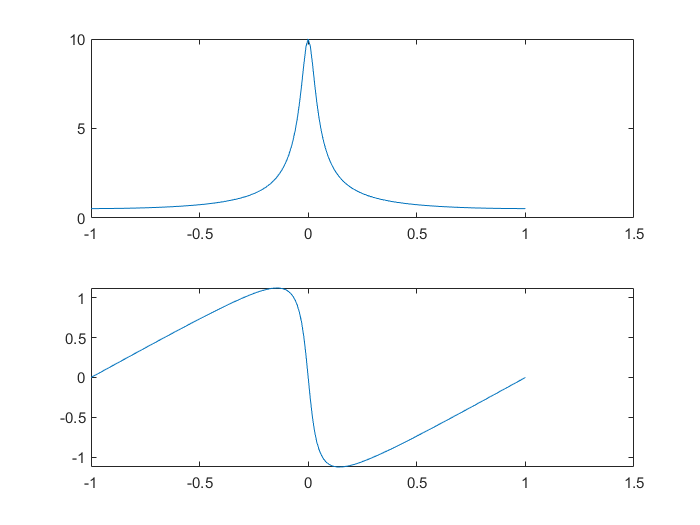

magH=abs(H);angH=angle(H);
figure(8)
subplot(2,1,1)
plot(w/pi,magH)
subplot(2,1,2)
xlabel("frequency in pi units");ylabel("|H|");title("Magnitude respone");
plot(w/pi,angH)
xlabel("frequency in pi units");ylabel("Phase in pi rad");title("Phase respone");

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

k=-100:100

k =   -100   -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51


w=(pi/100)*k

w =    -3.1416   -3.1102   -3.0788   -3.0473   -3.0159   -2.9845   -2.9531   -2.9217   -2.8903   -2.8588   -2.8274   -2.7960   -2.7646   -2.7332   -2.7018   -2.6704   -2.6389   -2.6075   -2.5761   -2.5447   -2.5133   -2.4819   -2.4504   -2.4190   -2.3876   -2.3562   -2.3248   -2.2934   -2.2619   -2.2305   -2.1991   -2.1677   -2.1363   -2.1049   -2.0735   -2.0420   -2.0106   -1.9792   -1.9478   -1.9164   -1.8850   -1.8535   -1.8221   -1.7907   -1.7593   -1.7279   -1.6965   -1.6650   -1.6336   -1.6022


H=exp(j*w)./(exp(j*w)-0.5*ones(1,201))+exp(j*w)/(exp(j*w)-0.4*ones(1,201))

H =    1.5275 - 0.0000i   1.5275 + 0.0070i   1.5276 + 0.0140i   1.5278 + 0.0210i   1.5281 + 0.0279i   1.5284 + 0.0350i   1.5288 + 0.0420i   1.5293 + 0.0490i   1.5299 + 0.0560i   1.5305 + 0.0631i   1.5312 + 0.0702i   1.5320 + 0.0773i   1.5329 + 0.0844i   1.5338 + 0.0916i   1.5349 + 0.0988i   1.5360 + 0.1060i   1.5372 + 0.1133i   1.5385 + 0.1206i   1.5399 + 0.1279i   1.5414 + 0.1353i   1.5430 + 0.1427i   1.5446 + 0.1502i   1.5464 + 0.1577i   1.5483 + 0.1653i   1.5503 + 0.1730i   1.5524 + 0.1807i   1.5547 + 0.1884i   1.5570 + 0.1962i   1.5595 + 0.2041i   1.5621 + 0.2121i   1.5649 + 0.2201i   1.5678 + 0.2282i   1.5708 + 0.2364i   1.5740 + 0.2447i   1.5774 + 0.2530i   1.5809 + 0.2614i   1.5846 + 0.2700i   1.5885 + 0.2786i   1.5926 + 0.2873i   1.5969 + 0.2961i   1.6014 + 0.3050i   1.6061 + 0.3140i   1.6110 + 0.3231i   1.6163 + 0.3324i   1.6217 + 0.3417i   1.6275 + 0.3511i   1.6335 + 0.3607i   1.6398 + 0.3703i   1.6465 + 0.3801i   1.6535 + 0.3900i


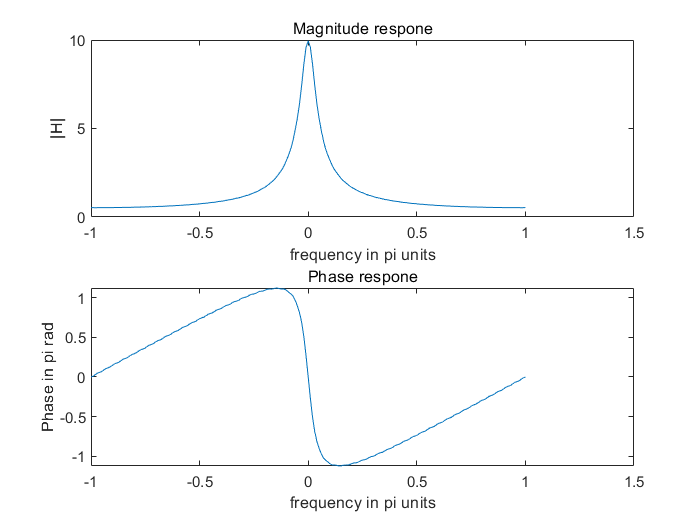

figure(9)
subplot(2,1,1)
plot(w/pi,magH)
xlabel("frequency in pi units");ylabel("|H|");title("Magnitude respone");
subplot(2,1,2)
plot(w/pi,angH)
xlabel("frequency in pi units");ylabel("Phase in pi rad");title("Phase respone");

5. (P3.17) 

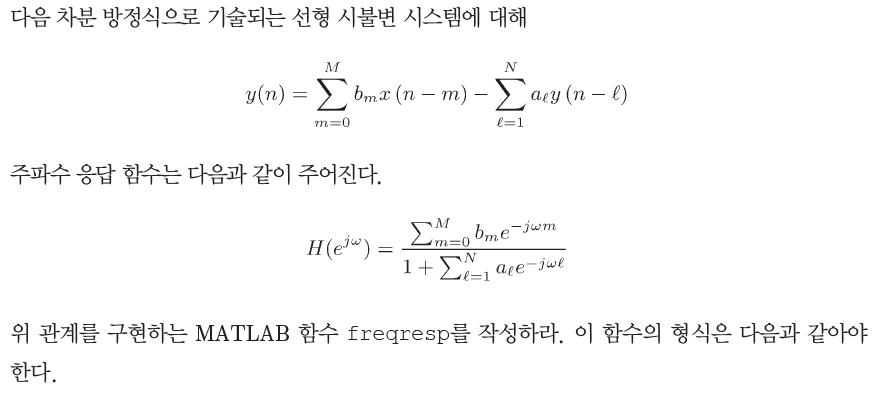

function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array
b = reshape(b,1,length(b))

b = 1

a = reshape(a,1,length(a))

a =     1.0000   -0.9000    0.8100   -0.7290    0.6561   -0.5905    0.5314   -0.4783    0.4305   -0.3874    0.3487   -0.3138    0.2824   -0.2542    0.2288   -0.2059    0.1853   -0.1668    0.1501   -0.1351    0.1216   -0.1094    0.0985   -0.0886    0.0798   -0.0718    0.0646   -0.0581    0.0523   -0.0471    0.0424   -0.0382    0.0343   -0.0309    0.0278   -0.0250    0.0225   -0.0203    0.0182   -0.0164    0.0148   -0.0133    0.0120   -0.0108    0.0097   -0.0087    0.0079   -0.0071    0.0064   -0.0057


w = reshape(w,1,length(w))

w =    -3.1416   -3.1102   -3.0788   -3.0473   -3.0159   -2.9845   -2.9531   -2.9217   -2.8903   -2.8588   -2.8274   -2.7960   -2.7646   -2.7332   -2.7018   -2.6704   -2.6389   -2.6075   -2.5761   -2.5447   -2.5133   -2.4819   -2.4504   -2.4190   -2.3876   -2.3562   -2.3248   -2.2934   -2.2619   -2.2305   -2.1991   -2.1677   -2.1363   -2.1049   -2.0735   -2.0420   -2.0106   -1.9792   -1.9478   -1.9164   -1.8850   -1.8535   -1.8221   -1.7907   -1.7593   -1.7279   -1.6965   -1.6650   -1.6336   -1.6022


m = 0:length(b)-1 

m = 0

num = b*exp(-j*m'*w)

num =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


l =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


l = 0:length(a)-1 
den = a*exp(-j*l'*w)

den =    9.9536 + 0.0000i   9.2384 - 2.5540i   7.5436 - 4.1915i   5.7569 - 4.7331i   4.4090 - 4.6384i   3.4765 - 4.3650i   2.7773 - 4.0473i   2.2617 - 3.6866i   1.9227 - 3.3459i   1.6819 - 3.0785i   1.4708 - 2.8497i   1.3026 - 2.6204i   1.1955 - 2.4164i   1.1128 - 2.2611i   1.0241 - 2.1244i   0.9505 - 1.9814i   0.9088 - 1.8541i   0.8735 - 1.7583i   0.8265 - 1.6703i   0.7876 - 1.5736i   0.7697 - 1.4876i   0.7524 - 1.4240i   0.7231 - 1.3630i   0.6999 - 1.2929i   0.6924 - 1.2311i   0.6829 - 1.1863i   0.6627 - 1.1413i   0.6477 - 1.0877i   0.6452 - 1.0411i   0.6396 - 1.0081i   0.6244 - 0.9732i   0.6142 - 0.9305i   0.6144 - 0.8941i   0.6108 - 0.8688i   0.5987 - 0.8408i   0.5915 - 0.8056i   0.5931 - 0.7763i   0.5906 - 0.7564i   0.5806 - 0.7331i   0.5755 - 0.7033i   0.5780 - 0.6792i   0.5760 - 0.6630i   0.5675 - 0.6432i   0.5638 - 0.6175i   0.5668 - 0.5972i   0.5652 - 0.5839i   0.5577 - 0.5665i   0.5551 - 0.5439i   0.5583 - 0.5266i   0.5568 - 0.5153i


H = num./(1+den);

end


6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$


k=-100:100

k =   -100   -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51


w=pi/100*k

w =    -3.1416   -3.1102   -3.0788   -3.0473   -3.0159   -2.9845   -2.9531   -2.9217   -2.8903   -2.8588   -2.8274   -2.7960   -2.7646   -2.7332   -2.7018   -2.6704   -2.6389   -2.6075   -2.5761   -2.5447   -2.5133   -2.4819   -2.4504   -2.4190   -2.3876   -2.3562   -2.3248   -2.2934   -2.2619   -2.2305   -2.1991   -2.1677   -2.1363   -2.1049   -2.0735   -2.0420   -2.0106   -1.9792   -1.9478   -1.9164   -1.8850   -1.8535   -1.8221   -1.7907   -1.7593   -1.7279   -1.6965   -1.6650   -1.6336   -1.6022


%손으로 H구한후 바로 적용한 식 입니다
H=(exp(2*j*w)-1*ones(1,201))./(exp(2*j*w)-0.95*exp(j*w)+0.9025*ones(1,201))

H =    0.0000 - 0.0000i   0.0000 + 0.0220i   0.0001 + 0.0441i   0.0002 + 0.0662i   0.0004 + 0.0883i   0.0006 + 0.1106i   0.0009 + 0.1329i   0.0012 + 0.1554i   0.0015 + 0.1781i   0.0020 + 0.2009i   0.0024 + 0.2239i   0.0030 + 0.2472i   0.0036 + 0.2707i   0.0042 + 0.2946i   0.0050 + 0.3187i   0.0057 + 0.3432i   0.0066 + 0.3680i   0.0075 + 0.3933i   0.0086 + 0.4190i   0.0097 + 0.4453i   0.0109 + 0.4720i   0.0122 + 0.4994i   0.0136 + 0.5273i   0.0151 + 0.5560i   0.0167 + 0.5854i   0.0185 + 0.6156i   0.0204 + 0.6467i   0.0225 + 0.6787i   0.0247 + 0.7117i   0.0272 + 0.7458i   0.0298 + 0.7812i   0.0327 + 0.8178i   0.0358 + 0.8559i   0.0392 + 0.8956i   0.0429 + 0.9370i   0.0470 + 0.9803i   0.0514 + 1.0256i   0.0563 + 1.0732i   0.0617 + 1.1234i   0.0677 + 1.1763i   0.0743 + 1.2323i   0.0817 + 1.2918i   0.0899 + 1.3552i   0.0992 + 1.4230i   0.1096 + 1.4957i   0.1215 + 1.5739i   0.1350 + 1.6586i   0.1505 + 1.7506i   0.1684 + 1.8511i   0.1893 + 1.9614i


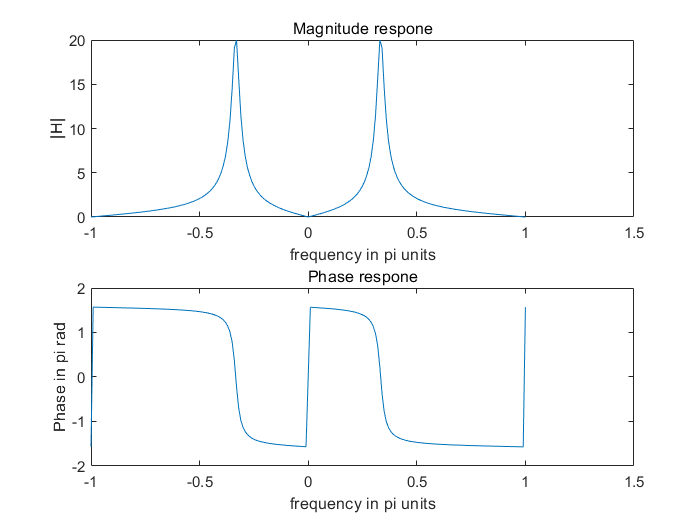

magH=abs(H);angH=angle(H);
figure(10)
subplot(2,1,1)
plot(w/pi,magH)
xlabel("frequency in pi units");ylabel("|H|");title("Magnitude respone");
subplot(2,1,2)
plot(w/pi,angH)
xlabel("frequency in pi units");ylabel("Phase in pi rad");title("Phase respone");

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

k=-100:100

k =   -100   -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51


w=pi/100*k

w =    -3.1416   -3.1102   -3.0788   -3.0473   -3.0159   -2.9845   -2.9531   -2.9217   -2.8903   -2.8588   -2.8274   -2.7960   -2.7646   -2.7332   -2.7018   -2.6704   -2.6389   -2.6075   -2.5761   -2.5447   -2.5133   -2.4819   -2.4504   -2.4190   -2.3876   -2.3562   -2.3248   -2.2934   -2.2619   -2.2305   -2.1991   -2.1677   -2.1363   -2.1049   -2.0735   -2.0420   -2.0106   -1.9792   -1.9478   -1.9164   -1.8850   -1.8535   -1.8221   -1.7907   -1.7593   -1.7279   -1.6965   -1.6650   -1.6336   -1.6022


%손으로 H구한후 바로 적용한 식 입니다
H=1./((exp(j*w)./(exp(j*w)-0.5*ones(1,201))).*(exp(-j*w)+exp(-2*j*w)+exp(-3*j*w)+exp(-4*j*w)+exp(-5*j*w))+ones(1,201))

H =    3.0000 + 0.0000i   2.8841 - 0.4753i   2.5997 - 0.8161i   2.2666 - 0.9875i   1.9654 - 1.0310i   1.7230 - 1.0004i   1.5374 - 0.9340i   1.3977 - 0.8535i   1.2926 - 0.7700i   1.2133 - 0.6884i   1.1530 - 0.6108i   1.1071 - 0.5376i   1.0721 - 0.4687i   1.0456 - 0.4036i   1.0258 - 0.3417i   1.0115 - 0.2822i   1.0018 - 0.2246i   0.9962 - 0.1683i   0.9941 - 0.1125i   0.9954 - 0.0566i   1.0000 + 0.0000i   1.0079 + 0.0581i   1.0192 + 0.1185i   1.0344 + 0.1821i   1.0539 + 0.2502i   1.0786 + 0.3241i   1.1097 + 0.4056i   1.1487 + 0.4973i   1.1984 + 0.6024i   1.2625 + 0.7255i   1.3473 + 0.8734i   1.4634 + 1.0565i   1.6296 + 1.2909i   1.8837 + 1.6034i   2.3097 + 2.0394i   3.1296 + 2.6678i   5.0692 + 3.4541i  10.2849 + 1.9960i   8.1105 - 7.9037i   1.9060 - 6.2712i   0.6793 - 4.1812i   0.4217 - 3.0596i   0.3746 - 2.3979i   0.3849 - 1.9659i   0.4122 - 1.6615i   0.4441 - 1.4342i   0.4766 - 1.2568i   0.5085 - 1.1132i   0.5395 - 0.9933i   0.5699 - 0.8904i


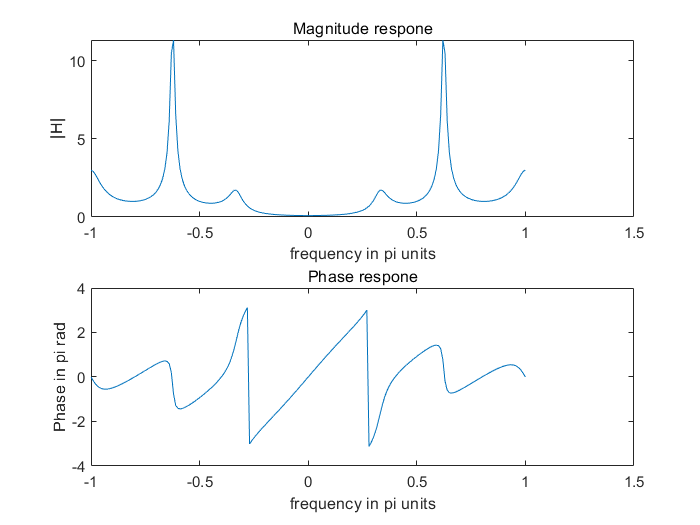

magH=abs(H);angH=angle(H);
figure(11)
subplot(2,1,1)
plot(w/pi,magH)
xlabel("frequency in pi units");ylabel("|H|");title("Magnitude respone");
subplot(2,1,2)
plot(w/pi,angH)
xlabel("frequency in pi units");ylabel("Phase in pi rad");title("Phase respone");


function [x,n] = stepseq(n0,n1,n2)
n = [n1:n2]; x = [(n-n0) >= 0];
end
function [y,ny] = conv_m(x,nx,h,nh)
nyb=nx(1)+nh(1);nye=nx(length(x))+nh(length(h));
ny=[nyb:nye];y=conv(x,h)
end

